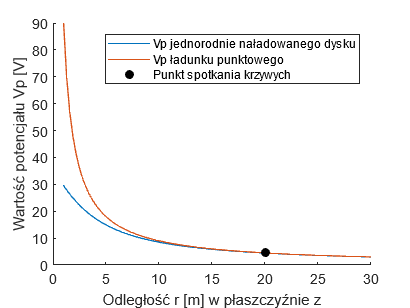

close all;
clear all;

% Tutaj jest tylko to co jest potrzebne do zadanie 2

% Promień koła
r = 5;

% Całościowy ładunek q
charge = 10e-9;

% Powierzchnia koła (dysku)
area = pi*r^2;

% Powierzchniowa gęstość ładunku (mała sigma)
surface_charge_density = charge/area;

% Przedział z, dla którego obliczamy potencjał
z = linspace(1, 30, 100);

% Stała elektrostatyczna
k = 9*10^9;

% Potencjał w odległości z dla ładunku punktowego
V = (k*charge)./z;

% Potencjał w odległości z dla jednorodnie naładowanego dysku
Vp = k*2*pi*surface_charge_density*(sqrt((z.^2)+(r^2))-sqrt(z.^2));

% Wykres
figure
hold on
plot(z, Vp)
plot(z, V)
scatter(z(66), V(66), MarkerFaceColor='black', MarkerEdgeColor='black', Marker='o')
hold off

% Własności wykresu
xlabel('Odległość r [m] w płaszczyźnie z')
ylabel('Wartość potencjału Vp [V]')
legend('Vp jednorodnie naładowanego dysku', 'Vp ładunku punktowego', 'Punkt spotkania krzywych')


% Mniejwięcej dla odległości 20 metrów można uznać taki dysk za ładunek
% punktowy